## Constante de Tempo

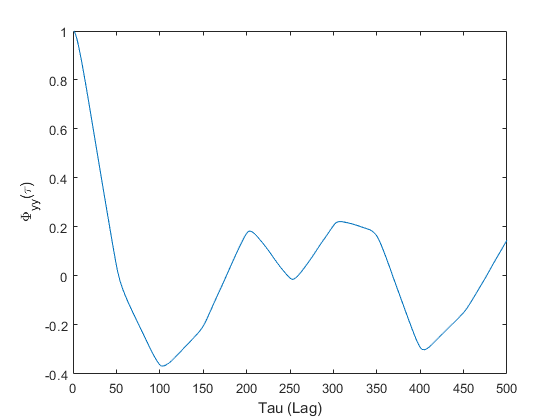

flag = [0 0];
temp = 1;
limite = N/2;

%Cálculo da autocovariância normalizada
phi1 = xcov(output,limite,'normalized');
phi2 = xcov(output.^2,limite,'normalized');


%Plotagem de Phi1
plot(phi1(limite+1:length(phi1))) 
%restrito a partir de limite+1 porque o phi varia no intervalo [-500,500]
xlim([0 limite])
xlabel('Tau (Lag)')
ylabel('\Phi_{yy}(\tau)')

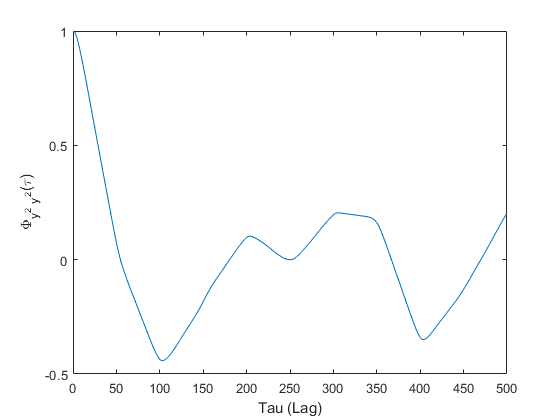


%Cálculo do instante do primeiro mínimo
for i=limite+1:length(phi1)
    if(phi1(i)<=temp)
        temp = phi1(i);
        flag(1) = i-limite-1;
    else
    break
    end
end

%Plotagem de Phi2
figure
plot(phi2(limite+1:length(phi2)))
%restrito a partir de limite+1 porque o phi varia no intervalo [-500,500]
xlim([0 limite])
xlabel('Tau (Lag)')
ylabel('\Phi_{y^2 y^2}(\tau)')


%Cálculo do instante do primeiro mínimo
temp = 1;
for i=limite+1:length(phi2)
    if(phi2(i)<=temp)
        temp = phi2(i);
        flag(2) = i-limite-1;
    else
        break
    end
end

%Intervalo do tempo de amostragem recomendado
tau = min(flag);
fprintf('Ts = [ %.3f, %.3f] \n',tau/20,tau/10);

Ts = [ 5.100, 10.200] 
